clc;
clear;
syms s Kpcr

G0 = Kpcr;
G1 = 1 / (s * (s+1) * (s+20));
G = G0 * G1;
H = 1;

G_mf_c = simplify(G / (1 + (G*H)))

$$G\_mf\_c = \frac{\mathrm{Kpcr}}{s^{3}+21\,s^{2}+20\,s+\mathrm{Kpcr}}$$


[~, den] = numden(G_mf_c);
den_coeffs = coeffs(den, s);
den_coeffs = flip(den_coeffs);

% Preenche a tabela de Routh
n = length(den_coeffs);
routh_table = sym(zeros(n, ceil(n/2)));
routh_table(1, 1:ceil(n/2)) = den_coeffs(1:2:end);
routh_table(2, 1:floor(n/2)) = den_coeffs(2:2:end);
for i = 3:n
    for j = 1:ceil(n/2)-1
        a = routh_table(i-1, 1);
        b = routh_table(i-1, j+1);
        c = routh_table(i-2, 1);
        d = routh_table(i-2, j+1);
        routh_table(i, j) = simplify((a * d - b * c) / a);
    end
end
disp('Tabela de Routh:');

Tabela de Routh:


disp(routh_table);

$$\left(\begin{array}{cc} 1 & 20\\ 21 & \mathrm{Kpcr}\\ 20-\frac{\mathrm{Kpcr}}{21} & 0\\ \mathrm{Kpcr} & 0 \end{array}\right)$$



ineq_Kpcr = 20 - (Kpcr/21) == 0

$$ineq\_Kpcr = 20-\frac{\mathrm{Kpcr}}{21}=0$$


Kpcr = double(solve(ineq_Kpcr, Kpcr))

Kpcr = 420


s = tf("s");

G = 1 / (s * (s+1) * (s+20))


G =
 
           1
  -------------------
  s^3 + 21 s^2 + 20 s
 
Continuous-time transfer function.
Model Properties


G_mf_c = feedback(Kpcr * G, 1)


G_mf_c =
 
             420
  -------------------------
  s^3 + 21 s^2 + 20 s + 420
 
Continuous-time transfer function.
Model Properties


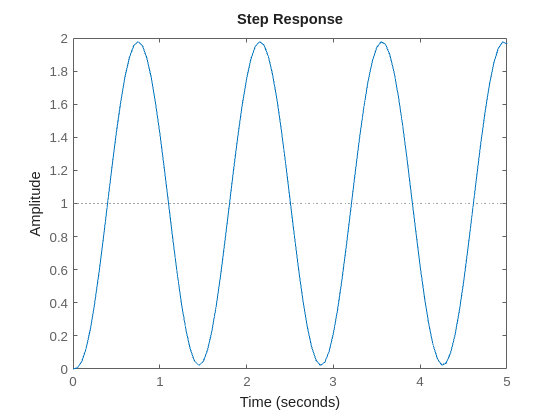


step(G_mf_c,5); 


Ppcr = 2.15 - 0.732 % acha pelo gráfico deve ser diferente no de vcs

Ppcr = 1.4180


Kp = double(0.6 * Kpcr)

Kp = 252

Ti = 0.5 * Ppcr

Ti = 0.7090

Td = 0.125 * Ppcr

Td = 0.1772


Gc = Kp * (1 + (1/(Ti*s)) + Td*s)


Gc =
 
  31.67 s^2 + 178.7 s + 252
  -------------------------
           0.709 s
 
Continuous-time transfer function.
Model Properties



a = 31.67/0.709;
b = 178.7/0.709;
c = 252/0.709;
fprintf("C(s) = (%.3f*s^2 + %.3f*s + %.3f)/s", a, b, c)

C(s) = (44.669*s^2 + 252.045*s + 355.430)/s


G_mf_c = feedback(Gc * G, 1)


G_mf_c =
 
              31.67 s^2 + 178.7 s + 252
  -------------------------------------------------
  0.709 s^4 + 14.89 s^3 + 45.85 s^2 + 178.7 s + 252
 
Continuous-time transfer function.
Model Properties


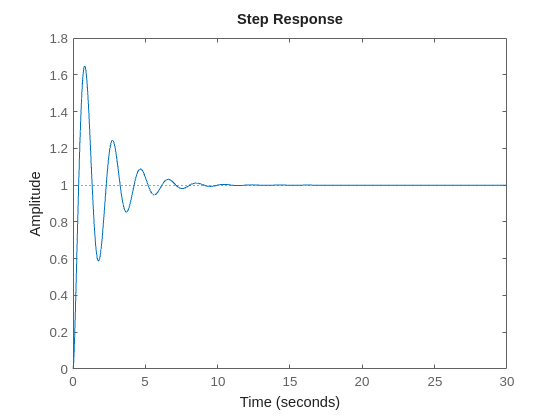

step(G_mf_c,30);


Mp = 1.6479 - 1;
Mp = Mp * 100

Mp = 64.7900





syms Td Ti

s_novo = -0.5

s_novo = -0.5000

eq_td = s_novo == -1/(2*Td)

$$eq\_td = -\frac{1}{2}=-\frac{1}{2\,\mathrm{Td}}$$

Td = double(solve(eq_td, Td))

Td = 1


eq_Ti = 4 * (Td/Ti) == 1

$$eq\_Ti = \frac{4}{\mathrm{Ti}}=1$$

Ti = double(solve(eq_Ti, Ti))

Ti = 4


Gc = Kp * (1 + (1/(Ti*s)) + Td*s)


Gc =
 
  1008 s^2 + 1008 s + 252
  -----------------------
            4 s
 
Continuous-time transfer function.
Model Properties


a = 1008/4;
b = 1008/4;
c = 252/4;
fprintf("C(s) = (%.3f*s^2 + %.3f*s + %.3f)/s", a, b, c)

C(s) = (252.000*s^2 + 252.000*s + 63.000)/s


G_mf_c = feedback(Gc * G, 1)


G_mf_c =
 
          1008 s^2 + 1008 s + 252
  ----------------------------------------
  4 s^4 + 84 s^3 + 1088 s^2 + 1008 s + 252
 
Continuous-time transfer function.
Model Properties


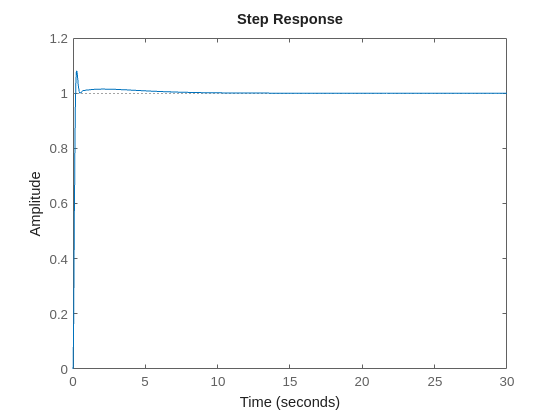

step(G_mf_c,30);


Mp = 1.08538 - 1;
Mp = Mp * 100

Mp = 8.5380